# Class Weight Histograms

This script specifically made to plot class weight histograms for Denges and Monte Ceneri 2017 for the platooning paper.

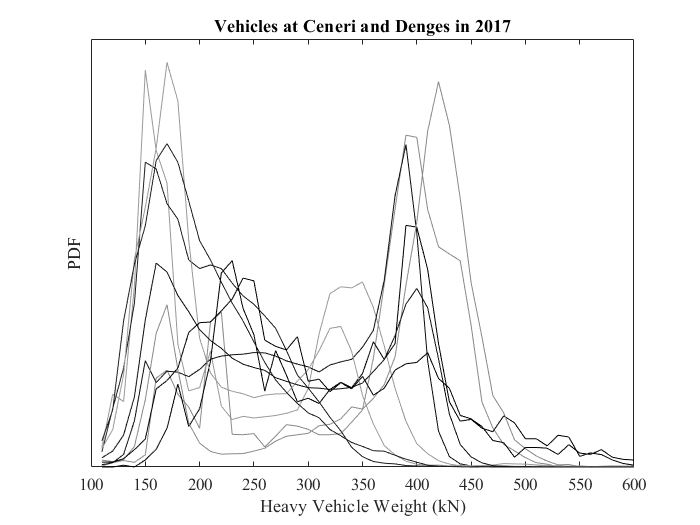

clear
clc
close all
format long g

% INPUT -----------
Year = 2017;
SName = {'Ceneri'; 'Denges'};

% Initialize Figure
figure
% Add title
title(sprintf('Vehicles at %s and %s in %i',SName{1},SName{2},Year),'FontName','times')
xlabel('Heavy Vehicle Weight (kN)','FontName','times')
ylabel('PDF','FontName','times')
box on
hold on
set(gca,'ytick',[],'yticklabel',[],'FontName','times')

% Set x values to be use globally
x_values = 0:1:1000;

% X Stuff
Step = 10;
LimitL = 100;
LimitR = 600;
X = LimitL:Step:LimitR;
x = X(1:end-1) + diff(X);

FaceAlpha = 0.7;

for i = 1:length(SName);
    
    % Load file
    load(['PrunedS1 WIM/',SName{i},'/',SName{i},'_',num2str(Year),'.mat']);
    
    % Let the Classify function add the .CLASS column to PD
    [PDC] = Classify(PD);
    
    % Must redo last two prunings because PDC draws fresh PD w/ only Stage 1
    % 1. Disqualification by weight (try under 6 or 10 tonnes)
    PDC = PDC(PDC.GW_TOT > 6000,:);
    % 2. Disqualification by Swiss10 Class (exclude 2,3,4,6)
    % Not all years have proper Sw10 data... therefore exclude, not include
    PDC(PDC.CS == 2 | PDC.CS == 3 | PDC.CS == 4 | PDC.CS == 6,:) = [];
    % Get rid of overweight classes and class 11bis
    PDC.CLASS(PDC.CLASS > 39 & PDC.CLASS < 50) = 0;
    PDC.CLASS(PDC.CLASS == 119) = 0;
    
    % TrTyps
    TrTyps = [11; 12; 22; 23; 111; 11117; 1127; 12117; 122; 11127; 1128; 1138; 1238];

    for j = [3, 4, 11, 12, 13]
        
        
        color{j} = ((13-j)/(13))*(200/255)*[1, 1, 1];
        
        y = histcounts(PDC.GW_TOT(PDC.CLASS == TrTyps(j))*0.00980665,'BinEdges',X,'normalization','pdf');
        plot(x,y,'color' ,color{j},'DisplayName',num2str(TrTyps))
        
        
        
    end
end